[I,i,t] = SA(1,20000)

I = 10

i = 10

t = 0.4998

[I_KN,t_KN] = KN(1)

I_KN = 10

t_KN = 0.2665

SA_result = zeros(40,4);
iValues = 1:5:200;

parfor idx = 1:numel(iValues)
	k = iValues(idx);
    temporary_result = zeros(50,3);
    for seed = 1:50
        [I,i,t]  = SA(seed*k,k*1000);
        temporary_result(seed,:) = [I,i,t];
    end
    temporary_result(:,[1,2]) = (temporary_result(:,[1,2]) == 10);
    SA_result(idx,:) = [k,mean(temporary_result,1)];
end

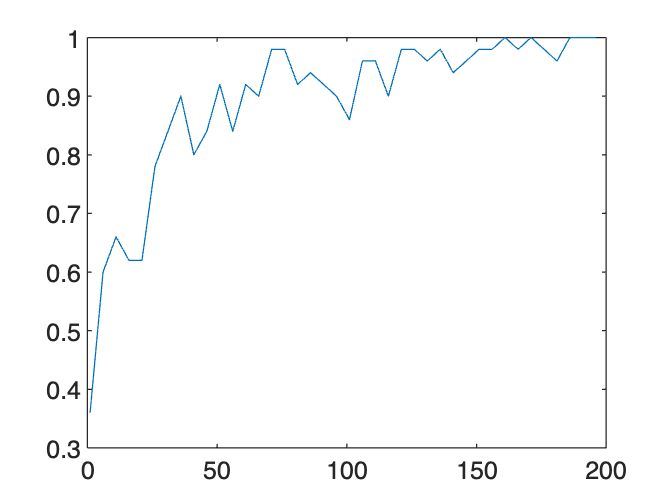

load("SA_result.mat")
plot(SA_result(:,1),SA_result(:,2))

### 比较SA与KN

result = zeros(1000,6);
parfor seed = 1:1000
    [I,i,t]  = SA(seed,100000);
    [I_KN,r_KN,t_KN] = KN(seed);
    result(seed,:) = [I,i,t,I_KN,r_KN,t_KN];
end

load("VS_result.mat")
result = VS_result;
result(:,[1,2,4]) = (result(:,[1,2,4]) == 10);
mean_result = mean(result(:,[1,2,3,4,6]),1)

mean_result =     0.9360    0.8770    2.2243    1.0000    0.5062


mean(result(:,5))

ans = 9.8936e+03